# Premier League Football Standings

Find the final team standings for the 2015-2016 English Premier League Football season.

The Excel® spreadsheet `EPLresults.xlsx` contains data for the 2015-2016 season of English Premier League football (soccer). The data includes wins, draws, losses, goals for, and goals against for each of the 20 teams, separated by home and away games.

## Load and sort the data.

Import the spreadsheet of EPL results programmatically.

EPL = readtable("EPLresults.xlsx");

Sort EPL by home wins, then by away wins, both in descending order.

EPL = sortrows(EPL,["HomeWins","AwayWins"],"descend");

## Home vs. Away wins

Compare home vs away records. Does there appear to be a home field advantage?

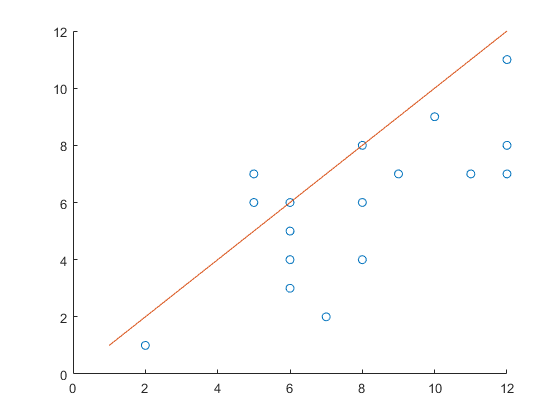

scatter(EPL.HomeWins,EPL.AwayWins)
hold on
plot([1,12],[1,12])
hold off

## Compute total points.

Calculate the total points for each team, where wins are worth 3 points, draws worth 1 point, and losses worth 0 points. Add the total points to the table as a new variable.

wins = EPL.HomeWins + EPL.AwayWins;
draws = EPL.HomeDraws + EPL.AwayDraws;
points = 3*wins + draws;
EPL.Points = points;

Sort table based on points.

EPL = sortrows(EPL,"Points","descend");

## Compute goal differential.

Calculate the goal differential by finding the difference between goals for (GF) and goals against (GA).

gf = EPL.HomeGF + EPL.AwayGF;
ga = EPL.HomeGA + EPL.AwayGA;
EPL.GD = gf - ga;

Find the league standings. Sort the table by points, and then by goal differential.

standings = EPL(:,["Team","Points","GD"]);
standings = sortrows(standings,["Points","GD"],"descend")

standings = 20×3 table
              Team              Points    GD 
    ________________________    ______    ___

    {'Leicester City'      }      81       32
    {'Arsenal'             }      71       29
    {'Tottenham Hotspur'   }      70       34
    {'Manchester City'     }      66       30
    {'Manchester United'   }      66       14
    {'Southampton'         }      63       18
    {'West Ham United'     }      62       14
    {'Liverpool'           }      60       13
    {'Stoke City'          }      51      -14
    {'Chelsea'             }      50        6
    {'Everton'             }      47        4
    {'Swansea City'        }      47      -10
    {'Watford'             }      45      -10
    {'West Bromwich Albion'}      43      -14
    {'Crystal Palace'      }      42      -12
    {'Bournemouth'         }      42      -22


## Export standings.

Save standings to an Excel spreadsheet and to a delimited text file.

writetable(standings,"EPLstandings.xlsx")